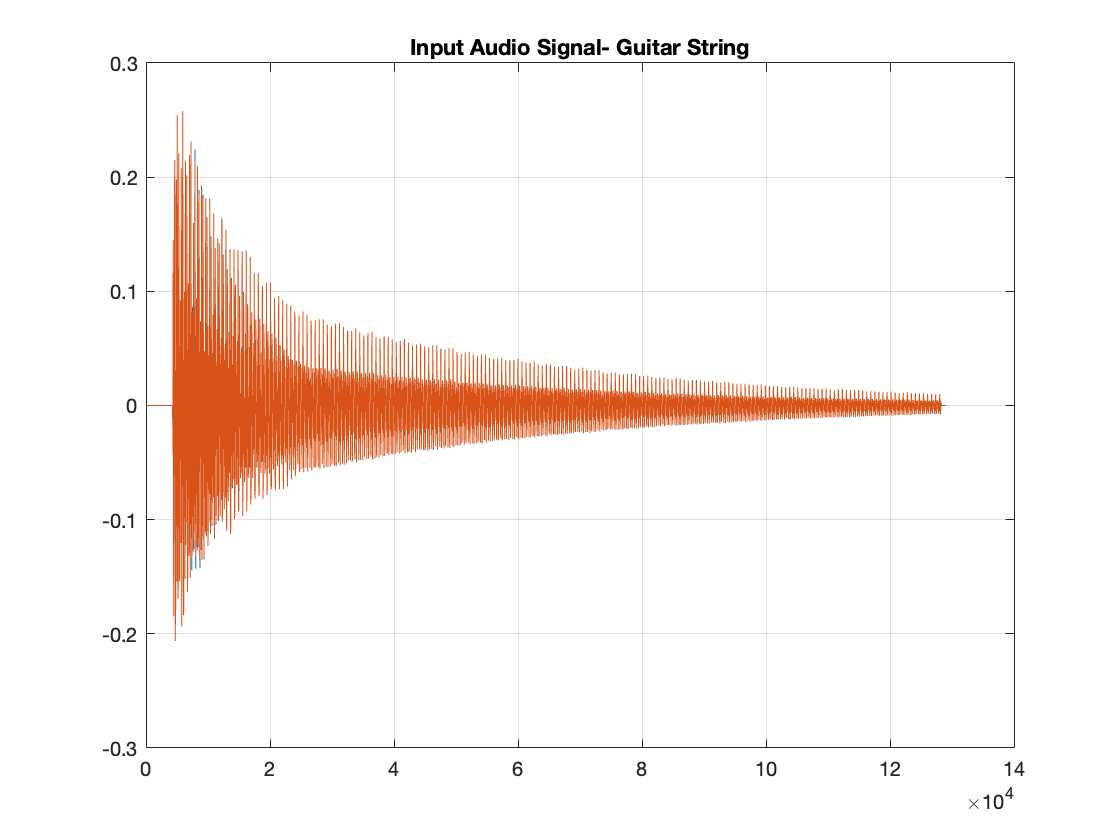

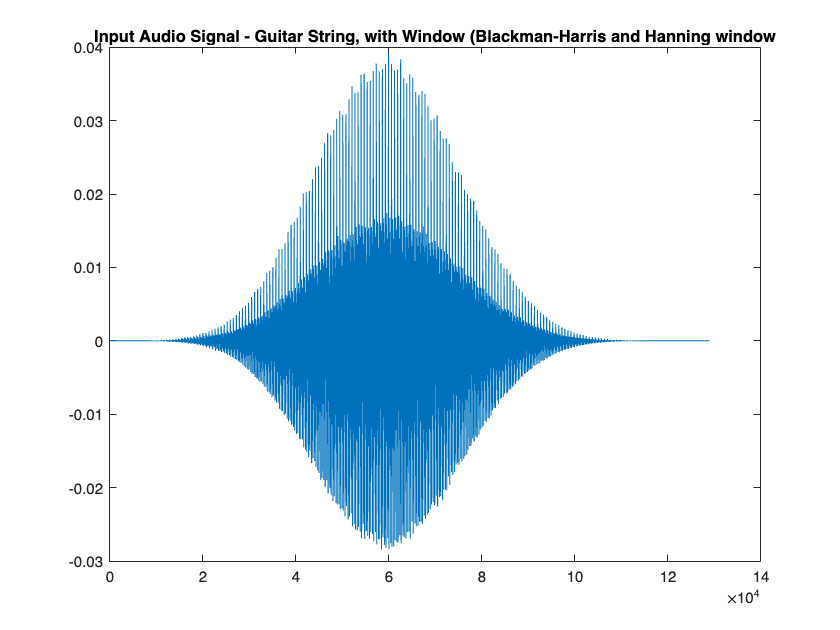

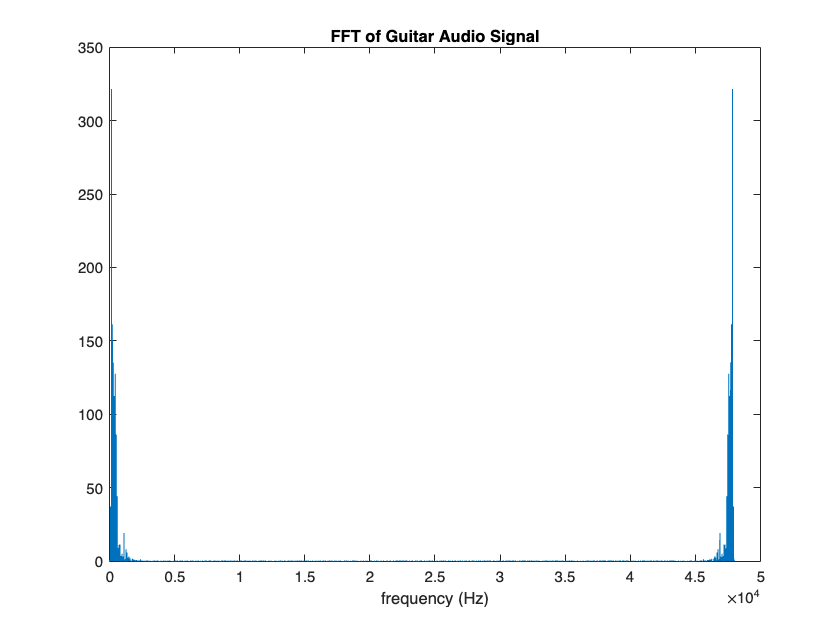

clear input; 

% Asking user to select audio file
filename = input("Enter the name of the audio file (including the file type): ", 's');

% Read in the audio signal
[y1, fs] = audioread(filename);

figure (1);
plot(y1); grid on; title('Input Audio Signal- Guitar String') 

userinput = input("What mode of tuning would you like to use? (1- Standard, 2- Drop 2, 3- Double Drop D, 4- DADGAD, 5- Open D: ", 's');

if (userinput=='1')
    StandardTuning(filename);
elseif (userinput== '2')
    DropDTuning(filename); 
elseif (userinput=='3')
    DoubleDropDTuning(filename); 
elseif(userinput=='4')
    DADGADTuning(filename); 
elseif(userinput=='5')
    OpenDTuning(filename);   
else
    disp("Wrong input!");
end 


% tuning modes: standard tuning (done!), drop d tuning (done!), double drop d, dadgad, open d

#### Standard

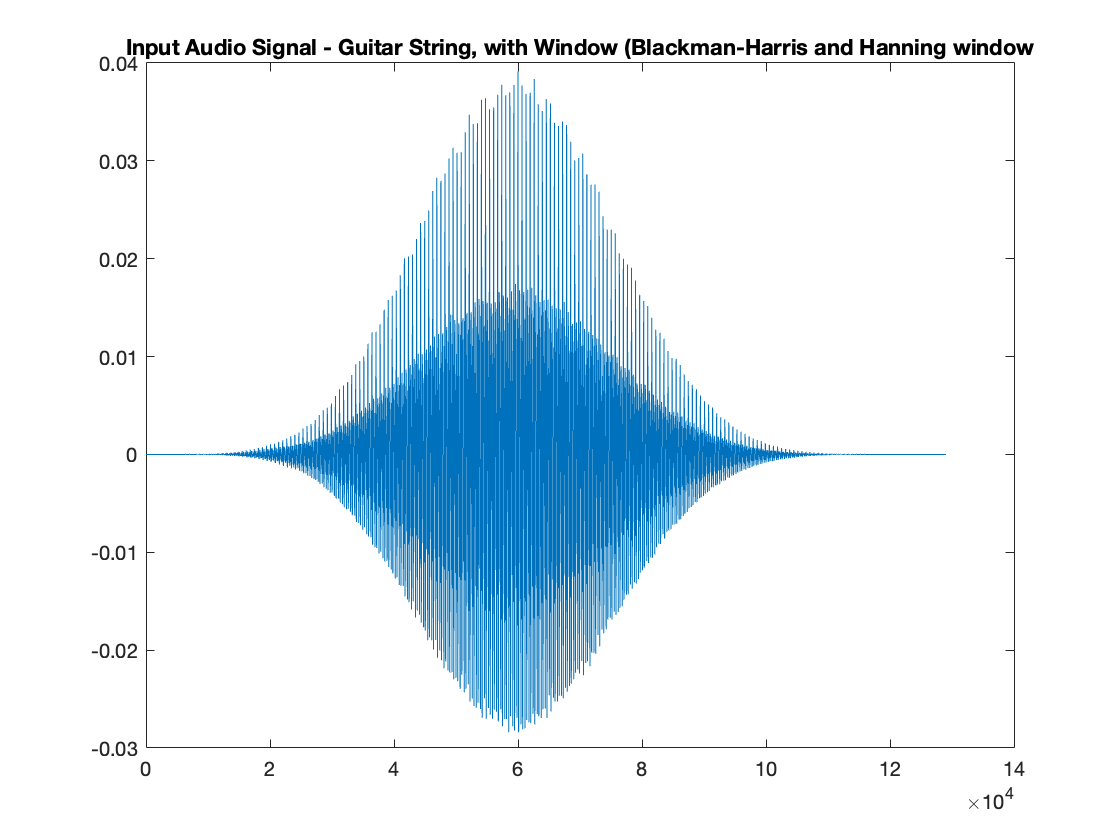

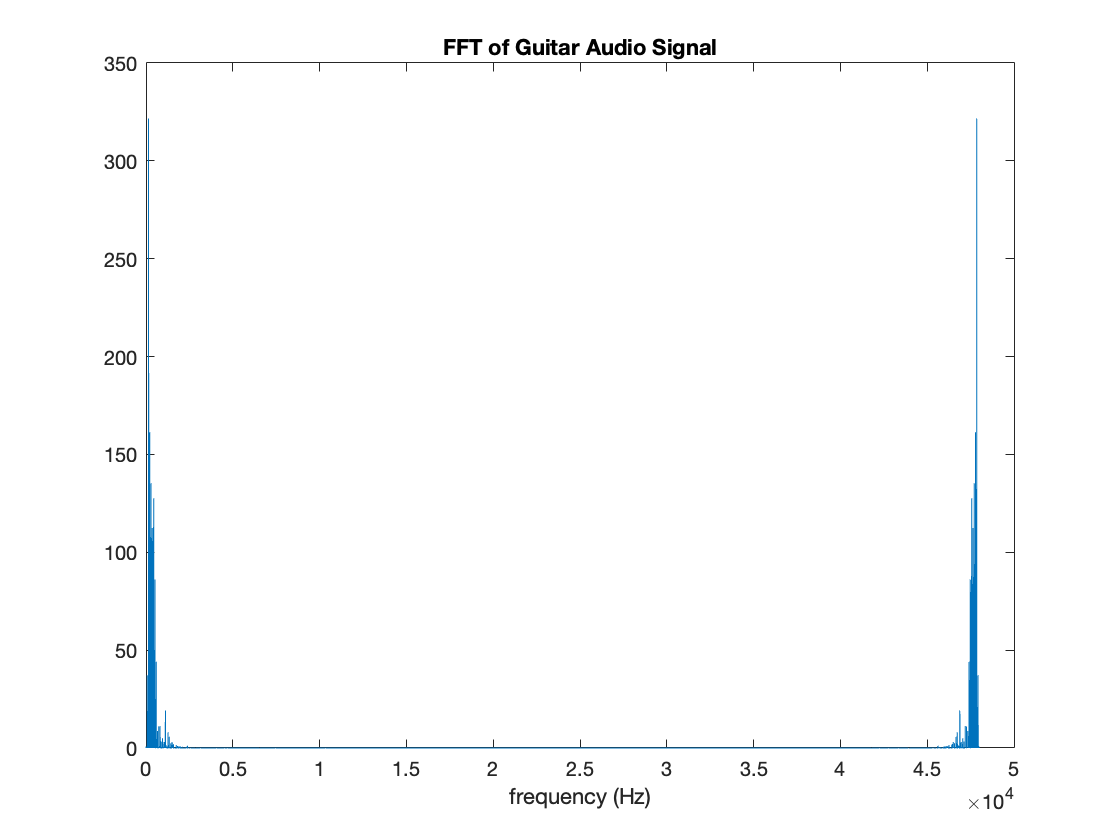

a = 321.6096

function x = StandardTuning (y)


% Read in the audio signal
[y1, fs] = audioread(y);

% Play the audio 
sound(y1, fs);

% Wait for the original sound to finish playing
pause(length(y1)/fs);

n = length(y1)-1; % determining last index of the array
f = 0:fs/n:fs; % time vector 
bh = blackmanharris(n+1); %Blackman-Harris Window
h = hanning(n+1); %Hanning Window

% Applying the window to the audio signal, 
y = y1(:,1).*bh.*h;

figure (2);
plot(y);title('Input Audio Signal - Guitar String, with Window (Blackman-Harris and Hanning window');

% Declaring standard fundamental frequency
E2 = 82.41;
A2 = 110;
D3 = 146.83;
G3 = 196.00;
B3 = 246.94;
E4 = 329.63;

% Declaring the bounds to be used for frequency filters so that the
% frequency has a tolerance to follow (For example, an input audio with a
% frequency of 85 will still be applicable in E2 for tune down and A2 for
% tune up. 
E2A2 = mean([E2 A2]);
A2D3 = mean([A2 D3]);
D3G3 = mean([D3 G3]);
G3B3 = mean([G3 B3]);
B3E4 = mean([B3 E4]);

% Declaring filter coefficients
E2filter = (1.*(f<E2A2).*(f>69))'; % creating a column vector that are true for elements of "f" that are greater than 70 and less than E2A2 (96.21).
A2filter = (1.*(f>E2A2).*(f<A2D3))';
D3filter = (1.*(f>A2D3).*(f<D3G3))';
G3filter = (1.*(f>D3G3).*(f<G3B3))';
B3filter = (1.*(f>G3B3).*(f<B3E4))';
E4filter = (1.*(f>B3E4).*(f<350))';

%FFT
y = abs(fft(y));
extract = y(:,1); %extract one column
figure(3); 
plot(f, extract ); title('FFT of Guitar Audio Signal'); xlabel('frequency (Hz)');

% using a 1.5 tolerance to check, 

%checking for E2
if(max(E2filter.*extract)> 500) 
 disp('Note: E2') %Displaying the note detected by the codes
 fSigE = E2filter.*extract; %Filter coefficients multiplied by one column from the FFT 
 [a, b] = max(fSigE); % getting the fundamental frequency 

 if(b*fs/n < E2-1.5)  
 disp('Comment: Tune up!');
 disp('Frequency difference:');
 disp(E2-1.5-(b*fs/n));

 elseif(E2+1.5 < b*fs/n)
 disp('Comment: Tune down!');
 disp('Frequency difference:');
 disp((b*fs/n)-E2+1.5);

 else
 disp('E2 is in tune!');
 end

%checking for A2
elseif(max(A2filter.*extract)> 1000)
 disp('Note: A2');
 fSigA = A2filter.*extract;
 [a1, b1] = max(fSigA);

 if(b1*fs/n < A2-1.5)
 disp('Comment: Tune up!');
 disp('Frequency difference:');
 disp(A2-1.5-(b1*fs/n));

 elseif(A2+1.5 < b1*fs/n)
 disp('Comment: Tune down!');
 disp('Frequency difference:');
 disp((b1*fs/n)-A2+1.5);

 else
 disp('A2 is in tune!');
 end

% checking for D3
elseif(max(D3filter.*extract)> 1000) 
 disp('Note: D3');
 fSigD = D3filter.*extract;
 [a2, b2] = max(fSigD);

 if(b2*fs/n < D3-1.5)
 disp('Comment: Tune up!');
 disp('Frequency difference:');
 disp(D3-1.5-(b2*fs/n));

 elseif(D3+1.5 < b2*fs/n)
 disp('Note: Tune down!');
 disp('Frequency difference:');
 disp((b2*fs/n)-D3+1.5);

 else
 disp('D3 is in tune!');
 end

 % checking for G3
elseif(max(G3filter.*extract)> 1000)
 disp('Note: G3');
 fSigG = G3filter.*extract;
 [a3, b3] = max(fSigG);

 if(b3*fs/n < G3-1.5)
 disp('Comment: Tune up!');
 disp('Frequency difference:');
 disp(G3-1.5-(b3*fs/n));

 elseif(G3+1.5 < b3*fs/n)
 disp('Comment: Tune down!');
 disp('Frequency difference:');
 disp((b3*fs/n)-G3+1.5);

 else
 disp('G3 is in tune!');
 end

% checking for B3
elseif(max(B3filter.*extract)> 1000)
 disp('Note: B3');
 fSigB = B3filter.*extract;
 [a4, b4] = max(fSigB);

 if(b4*fs/n < B3-1.5)
 disp('Comment: Tune up!');
 disp('Frequency difference:');
 disp(B3-1.5-(b4*fs/n));

 elseif(B3+1.5 < b4*fs/n)
 disp('Comment: Tune down!');
 disp('Frequency difference:');
 disp((b4*fs/n)-B3+1.5);

 else
 disp('B3 is in tune!');
 end

 % checking for E4
elseif(max(E4filter.*extract)> 1000)
 disp('Note: E4');
 fSigE1 = E4filter.*extract;
 [a5, b5] = max(fSigE1);

 if(B5*fs/n < E4-1.5)
 disp('Comment: Tune up!');
 disp('Frequency difference:');
 disp(E4-1.5-(b5*fs/n));

 elseif(E4+1.5 < b5*fs/n)
 disp('Comment: Tune down!');
 disp('Frequency difference:');
 disp((b5*fs/n)-E4+1.5);

 else
 disp('E4 is in tune!');
 end

end
end 

#### Drop D

function x = DropDTuning (y)

% Read in the audio signal
[y1, fs] = audioread(y);

% Play the audio 
sound(y1, fs);

% Wait for the original sound to finish playing
pause(length(y1)/fs);

n = length(y1)-1; % determining last index of the array
f = 0:fs/n:fs; % time vector 
bh = blackmanharris(n+1); %Blackman-Harris Window
h = hanning(n+1); %Hanning Window

% Applying the window to the audio signal, 
y = y1(:,1).*bh.*h;

figure (2);
plot(y);title('Input Audio Signal - Guitar String, with Window (Blackman-Harris and Hanning window');

% Declaring drop d fundamental frequency
D2 = 73.42;
A2 = 110;
D3 = 146.83;
G3 = 196;
B3 = 246.94;
E4 = 329.63;

% Declaring the bounds to be used for frequency filters so that the
% frequency has a tolerance to follow (For example, an input audio with a
% frequency of 85 will still be applicable in E2 for tune down and A2 for
% tune up. 
D2A2 = mean([D2 A2]);
A2D3 = mean([A2 D3]);
D3G3 = mean([D3 G3]);
G3B3 = mean([G3 B3]);
B3E4 = mean([B3 E4]);

% Declaring filter coefficients
D2filter = (1.*(f<D2A2).*(f>69))'; % creating a column vector that are true for elements of "f" that are greater than 70 and less than E2A2 (96.21).
A2filter = (1.*(f>D2A2).*(f<A2D3))';
D3filter = (1.*(f>A2D3).*(f<D3G3))';
G3filter = (1.*(f>D3G3).*(f<G3B3))';
B3filter = (1.*(f>G3B3).*(f<B3E4))';
E4filter = (1.*(f>B3E4).*(f<350))';

%FFT
y = abs(fft(y));
extract = y(:,1); %extract one column
figure(3); 
plot(f, extract ); title('FFT of Guitar Audio Signal'); xlabel('frequency (Hz)');

% using a 1.5 tolerance to check, 

%checking for D2
if(max(D2filter.*extract)> 500) 
 disp('Note: D2') %Displaying the note detected by the codes
 fSigE = D2filter.*extract; %Filter coefficients multiplied by one column from the FFT 
 [a, b] = max(fSigE); % getting the fundamental frequency 

 if(b*fs/n < D2-1.5)  
 disp('Comment: Tune up!');
 disp('Frequency difference:');
 disp(D2-1.5-(b*fs/n));

 elseif(D2+1.5 < b*fs/n)
 disp('Comment: Tune down!');
 disp('Frequency difference:');
 disp((b*fs/n)-D2+1.5);

 else
 disp('D2 is in tune!');
 end

%checking for A2
elseif(max(A2filter.*extract)> 1000)
 disp('Note: A2');
 fSigA = A2filter.*extract;
 [a1, b1] = max(fSigA);

 if(b1*fs/n < A2-1.5)
 disp('Comment: Tune up!');
 disp('Frequency difference:');
 disp(A2-1.5-(b1*fs/n));

 elseif(A2+1.5 < b1*fs/n)
 disp('Comment: Tune down!');
 disp('Frequency difference:');
 disp((b1*fs/n)-A2+1.5);

 else
 disp('A2 is in tune!');
 end

% checking for D3
elseif(max(D3filter.*extract)> 1000) 
 disp('Note: D3');
 fSigD = D3filter.*extract;
 [a2, b2] = max(fSigD);

 if(b2*fs/n < D3-1.5)
 disp('Comment: Tune up!');
 disp('Frequency difference:');
 disp(D3-1.5-(b2*fs/n));

 elseif(D3+1.5 < b2*fs/n)
 disp('Note: Tune down!');
 disp('Frequency difference:');
 disp((b2*fs/n)-D3+1.5);

 else
 disp('D3 is in tune!');
 end

 % checking for G3
elseif(max(G3filter.*extract)> 1000)
 disp('Note: G3');
 fSigG = G3filter.*extract;
 [a3, b3] = max(fSigG);

 if(b3*fs/n < G3-1.5)
 disp('Comment: Tune up!');
 disp('Frequency difference:');
 disp(G3-1.5-(b3*fs/n));

 elseif(G3+1.5 < b3*fs/n)
 disp('Comment: Tune down!');
 disp('Frequency difference:');
 disp((b3*fs/n)-G3+1.5);

 else
 disp('G3 is in tune!');
 end

% checking for B3
elseif(max(B3filter.*extract)> 1000)
 disp('Note: B3');
 fSigB = B3filter.*extract;
 [a4, b4] = max(fSigB);

 if(b4*fs/n < B3-1.5)
 disp('Comment: Tune up!');
 disp('Frequency difference:');
 disp(B3-1.5-(b4*fs/n));

 elseif(B3+1.5 < b4*fs/n)
 disp('Comment: Tune down!');
 disp('Frequency difference:');
 disp((b4*fs/n)-B3+1.5);

 else
 disp('B3 is in tune!');
 end

 % checking for E4
elseif(max(E4filter.*extract)> 1000)
 disp('Note: E4');
 fSigE1 = E4filter.*extract;
 [a5, b5] = max(fSigE1);

 if(B5*fs/n < E4-1.5)
 disp('Comment: Tune up!');
 disp('Frequency difference:');
 disp(E4-1.5-(b5*fs/n));

 elseif(E4+1.5 < b5*fs/n)
 disp('Comment: Tune down!');
 disp('Frequency difference:');
 disp((b5*fs/n)-E4+1.5);

 else
 disp('E4 is in tune!');
 end

end
end 

#### Double Drop D

function x = DoubleDropDTuning (y)

% Read in the audio signal
[y1, fs] = audioread(y);

% Play the audio 
sound(y1, fs);

% Wait for the original sound to finish playing
pause(length(y1)/fs);

n = length(y1)-1; % determining last index of the array
f = 0:fs/n:fs; % time vector 
bh = blackmanharris(n+1); %Blackman-Harris Window
h = hanning(n+1); %Hanning Window

% Applying the window to the audio signal, 
y = y1(:,1).*bh.*h;

figure (2);
plot(y);title('Input Audio Signal - Guitar String, with Window (Blackman-Harris and Hanning window');

% Declaring double drop d fundamental frequency
D1 = 73.7;
A1 = 110;
D2 = 147;
G1 = 196;
B1 = 247;
D3 = 294;

% Declaring the bounds to be used for frequency filters so that the
% frequency has a tolerance to follow (For example, an input audio with a
% frequency of 85 will still be applicable in E2 for tune down and A2 for
% tune up. 
D1A1 = mean([D1 A1]);
A1D2 = mean([A1 D2]);
D2G1 = mean([D2 G1]);
G1B1 = mean([G1 B1]);
B1D3 = mean([B1 D3]);

% Declaring filter coefficients
D1filter = (1.*(f<D1A1).*(f>69))'; % creating a column vector that are true for elements of "f" that are greater than 70 and less than E2A2 (96.21).
A1filter = (1.*(f>D1A1).*(f<A1D2))';
D2filter = (1.*(f>A1D2).*(f<D2G1))';
G1filter = (1.*(f>D2G1).*(f<G1B1))';
B1filter = (1.*(f>G1B1).*(f<B1D3))';
D3filter = (1.*(f>B1D3).*(f<300))';

%FFT
y = abs(fft(y));
extract = y(:,1); %extract one column
figure(3); 
plot(f, extract ); title('FFT of Guitar Audio Signal'); xlabel('frequency (Hz)');

% using a 1.5 tolerance to check, 

%checking for D1
if(max(D1filter.*extract)> 500) 
 disp('Note: D1') %Displaying the note detected by the codes
 fSigE = D1filter.*extract; %Filter coefficients multiplied by one column from the FFT 
 [a, b] = max(fSigE); % getting the fundamental frequency 

 if(b*fs/n < D1-1.5)  
 disp('Comment: Tune up!');
 disp('Frequency difference:');
 disp(D1-1.5-(b*fs/n));

 elseif(D1+1.5 < b*fs/n)
 disp('Comment: Tune down!');
 disp('Frequency difference:');
 disp((b*fs/n)-D1+1.5);

 else
 disp('D1 is in tune!');
 end

%checking for A1
elseif(max(A1filter.*extract)> 1000)
 disp('Note: A1');
 fSigA = A1filter.*extract;
 [a1, b1] = max(fSigA);

 if(b1*fs/n < A1-1.5)
 disp('Comment: Tune up!');
 disp('Frequency difference:');
 disp(A1-1.5-(b1*fs/n));

 elseif(A1+1.5 < b1*fs/n)
 disp('Comment: Tune down!');
 disp('Frequency difference:');
 disp((b1*fs/n)-A1+1.5);

 else
 disp('A1 is in tune!');
 end

% checking for D2
elseif(max(D2filter.*extract)> 1000) 
 disp('Note: D2');
 fSigD = D2filter.*extract;
 [a2, b2] = max(fSigD);

 if(b2*fs/n < D2-1.5)
 disp('Comment: Tune up!');
 disp('Frequency difference:');
 disp(D2-1.5-(b2*fs/n));

 elseif(D2+1.5 < b2*fs/n)
 disp('Note: Tune down!');
 disp('Frequency difference:');
 disp((b2*fs/n)-D2+1.5);

 else
 disp('D2 is in tune!');
 end

 % checking for G1
elseif(max(G1filter.*extract)> 1000)
 disp('Note: G1');
 fSigG = G1filter.*extract;
 [a3, b3] = max(fSigG);

 if(b3*fs/n < G1-1.5)
 disp('Comment: Tune up!');
 disp('Frequency difference:');
 disp(G1-1.5-(b3*fs/n));

 elseif(G1+1.5 < b3*fs/n)
 disp('Comment: Tune down!');
 disp('Frequency difference:');
 disp((b3*fs/n)-G1+1.5);

 else
 disp('G1 is in tune!');
 end

% checking for B1
elseif(max(B1filter.*extract)> 1000)
 disp('Note: B1');
 fSigB = B1filter.*extract;
 [a4, b4] = max(fSigB);

 if(b4*fs/n < B1-1.5)
 disp('Comment: Tune up!');
 disp('Frequency difference:');
 disp(B1-1.5-(b4*fs/n));

 elseif(B1+1.5 < b4*fs/n)
 disp('Comment: Tune down!');
 disp('Frequency difference:');
 disp((b4*fs/n)-B1+1.5);

 else
 disp('B1 is in tune!');
 end

 % checking for D3
elseif(max(D3filter.*extract)> 1000)
 disp('Note: D3');
 fSigD3 = D3filter.*extract;
 [a5, b5] = max(fSigD3);

 if(b5*fs/n < E4-1.5)
 disp('Comment: Tune up!');
 disp('Frequency difference:');
 disp(D3-1.5-(b5*fs/n));

 elseif(D3+1.5 < b5*fs/n)
 disp('Comment: Tune down!');
 disp('Frequency difference:');
 disp((b5*fs/n)-D3+1.5);

 else
 disp('D3 is in tune!');
 end

end
end 

#### DADGAD

function x = DADGADTuning (y)

% Read in the audio signal
[y1, fs] = audioread(y);

% Play the audio 
sound(y1, fs);

% Wait for the original sound to finish playing
pause(length(y1)/fs);

n = length(y1)-1; % determining last index of the array
f = 0:fs/n:fs; % time vector 
bh = blackmanharris(n+1); %Blackman-Harris Window
h = hanning(n+1); %Hanning Window

% Applying the window to the audio signal, 
y = y1(:,1).*bh.*h;

figure (2);
plot(y);title('Input Audio Signal - Guitar String, with Window (Blackman-Harris and Hanning window');

% Declaring standard fundamental frequency
D2 = 73.42;
A2 = 110;
D3 = 146.83;
G3 = 196;
A3 = 220;
D4 = 293.66;

% Declaring the bounds to be used for frequency filters so that the
% frequency has a tolerance to follow

D2A2 = mean([D2 A2]);
A2D3 = mean([A2 D3]);
D3G3 = mean([D3 G3]);
G3A3 = mean([G3 A3]);
A3D4 = mean([A3 D4]);

% Declaring filter coefficients
D2filter = (1.*(f<D2A2).*(f>40))';
A2filter = (1.*(f>D2A2).*(f<A2D3))';
D3filter = (1.*(f>A2D3).*(f<D3G3))';
G3filter = (1.*(f>D3G3).*(f<G3A3))';
A3filter = (1.*(f>G3A3).*(f<A3D4))';
D4filter = (1.*(f>A3D4).*(f<350))';

%FFT
y = abs(fft(y));
extract = y(:,1); %extract one column
figure(3); 
plot(f, extract ); title('FFT of Guitar Audio Signal'); xlabel('frequency (Hz)');

% using a 1.5 tolerance to check, 

%checking for D2
if(max(D2filter.*extract)> 500) 
 disp('Note: D2') %Displaying the note detected by the codes
 fSigD = D2filter.*extract; %Filter coefficients multiplied by one column from the FFT 
 [a, b] = max(fSigD); % getting the fundamental frequency 

 if(b*fs/n < D2-1.5)  
 disp('Comment: Tune up!');
 disp('Frequency difference:');
 disp(D2-1.5-(b*fs/n));

 elseif(D2+1.5 < b*fs/n)
 disp('Comment: Tune down!');
 disp('Frequency difference:');
 disp((b*fs/n)-D2+1.5);

 else
 disp('D2 is in tune!');
 end

%checking for A2
elseif(max(A2filter.*extract)> 1000)
 disp('Note: A2');
 fSigA = A2filter.*extract;
 [a1, b1] = max(fSigA);

 if(b1*fs/n < A2-1.5)
 disp('Comment: Tune up!');
 disp('Frequency difference:');
 disp(A2-1.5-(b1*fs/n));

 elseif(A2+1.5 < b1*fs/n)
 disp('Comment: Tune down!');
 disp('Frequency difference:');
 disp((b1*fs/n)-A2+1.5);

 else
 disp('A2 is in tune!');
 end

% checking for D3
elseif(max(D3filter.*extract)> 1000) 
 disp('Note: D3');
 fSigD = D3filter.*extract;
 [a2, b2] = max(fSigD);

 if(b2*fs/n < D3-1.5)
 disp('Comment: Tune up!');
 disp('Frequency difference:');
 disp(D3-1.5-(b2*fs/n));

 elseif(D3+1.5 < b2*fs/n)
 disp('Note: Tune down!');
 disp('Frequency difference:');
 disp((b2*fs/n)-D3+1.5);

 else
 disp('D3 is in tune!');
 end

 % checking for G3
elseif(max(G3filter.*extract)> 1000)
 disp('Note: G3');
 fSigG = G3filter.*extract;
 [a3, b3] = max(fSigG);

 if(b3*fs/n < G3-1.5)
 disp('Comment: Tune up!');
 disp('Frequency difference:');
 disp(G3-1.5-(b3*fs/n));

 elseif(G3+1.5 < b3*fs/n)
 disp('Comment: Tune down!');
 disp('Frequency difference:');
 disp((b3*fs/n)-G3+1.5);

 else
 disp('G3 is in tune!');
 end

% checking for A3
elseif(max(A3filter.*extract)> 1000)
 disp('Note: A3');
 fSigA = A3filter.*extract;
 [a4, b4] = max(fSigA);

 if(b4*fs/n < A3-1.5)
 disp('Comment: Tune up!');
 disp('Frequency difference:');
 disp(A3-1.5-(b4*fs/n));

 elseif(A3+1.5 < b4*fs/n)
 disp('Comment: Tune down!');
 disp('Frequency difference:');
 disp((b4*fs/n)-A3+1.5);

 else
 disp('A3 is in tune!');
 end

 % checking for D4
elseif(max(D4filter.*extract)> 1000)
 disp('Note: D4');
 fSigD1 = D4filter.*extract;
 [a5, b5] = max(fSigD1);

 if(B5*fs/n < D4-1.5)
 disp('Comment: Tune up!');
 disp('Frequency difference:');
 disp(D4-1.5-(b5*fs/n));

 elseif(D4+1.5 < b5*fs/n)
 disp('Comment: Tune down!');
 disp('Frequency difference:');
 disp((b5*fs/n)-D4+1.5);

 else
 disp('D4 is in tune!');
 end

end
end 

**Open D**

function x = OpenDTuning (y)

% Read in the audio signal
[y1, fs] = audioread(y);

% Play the audio 
sound(y1, fs);

% Wait for the original sound to finish playing
pause(length(y1)/fs);

n = length(y1)-1; % determining last index of the array
f = 0:fs/n:fs; % time vector 
bh = blackmanharris(n+1); %Blackman-Harris Window
h = hanning(n+1); %Hanning Window

% Applying the window to the audio signal, 
y = y1(:,1).*bh.*h;

figure (2);
plot(y);title('Input Audio Signal - Guitar String, with Window (Blackman-Harris and Hanning window');

% Declaring standard fundamental frequency
D2 = 73.42;
A2 = 110;
D3 = 146.83;
GB3 = 185;
A3 = 220;
D4 = 293.66;

% Declaring the bounds to be used for frequency filters so that the
% frequency has a tolerance to follow

D2A2 = mean([D2 A2]);
A2D3 = mean([A2 D3]);
D3GB3 = mean([D3 GB3]);
GB3A3 = mean([GB3 A3]);
A3D4 = mean([A3 D4]);

% Declaring filter coefficients
D2filter = (1.*(f<D2A2).*(f>40))';
A2filter = (1.*(f>D2A2).*(f<A2D3))';
D3filter = (1.*(f>A2D3).*(f<D3GB3))';
GB3filter = (1.*(f>D3GB3).*(f<GB3A3))';
A3filter = (1.*(f>GB3A3).*(f<A3D4))';
D4filter = (1.*(f>A3D4).*(f<350))';

%FFT
y = abs(fft(y));
extract = y(:,1); %extract one column
figure(3); 
plot(f, extract ); title('FFT of Guitar Audio Signal'); xlabel('frequency (Hz)');

% using a 1.5 tolerance to check, 

%checking for D2
if(max(D2filter.*extract)> 500) 
 disp('Note: D2') %Displaying the note detected by the codes
 fSigD = D2filter.*extract; %Filter coefficients multiplied by one column from the FFT 
 [a, b] = max(fSigD); % getting the fundamental frequency 

 if(b*fs/n < D2-1.5)  
 disp('Comment: Tune up!');
 disp('Frequency difference:');
 disp(D2-1.5-(b*fs/n));

 elseif(D2+1.5 < b*fs/n)
 disp('Comment: Tune down!');
 disp('Frequency difference:');
 disp((b*fs/n)-D2+1.5);

 else
 disp('D2 is in tune!');
 end

%checking for A2
elseif(max(A2filter.*extract)> 1000)
 disp('Note: A2');
 fSigA = A2filter.*extract;
 [a1, b1] = max(fSigA);

 if(b1*fs/n < A2-1.5)
 disp('Comment: Tune up!');
 disp('Frequency difference:');
 disp(A2-1.5-(b1*fs/n));

 elseif(A2+1.5 < b1*fs/n)
 disp('Comment: Tune down!');
 disp('Frequency difference:');
 disp((b1*fs/n)-A2+1.5);

 else
 disp('A2 is in tune!');
 end

% checking for D3
elseif(max(D3filter.*extract)> 1000) 
 disp('Note: D3');
 fSigD = D3filter.*extract;
 [a2, b2] = max(fSigD);

 if(b2*fs/n < D3-1.5)
 disp('Comment: Tune up!');
 disp('Frequency difference:');
 disp(D3-1.5-(b2*fs/n));

 elseif(D3+1.5 < b2*fs/n)
 disp('Note: Tune down!');
 disp('Frequency difference:');
 disp((b2*fs/n)-D3+1.5);

 else
 disp('D3 is in tune!');
 end

 % checking for GB3
elseif(max(GB3filter.*extract)> 1000)
 disp('Note: GB3');
 fSigG = GB3filter.*extract;
 [a3, b3] = max(fSigG);

 if(b3*fs/n < GB3-1.5)
 disp('Comment: Tune up!');
 disp('Frequency difference:');
 disp(GB3-1.5-(b3*fs/n));

 elseif(GB3+1.5 < b3*fs/n)
 disp('Comment: Tune down!');
 disp('Frequency difference:');
 disp((b3*fs/n)-GB3+1.5);

 else
 disp('GB3 is in tune!');
 end

% checking for A3
elseif(max(A3filter.*extract)> 1000)
 disp('Note: A3');
 fSigA = A3filter.*extract;
 [a4, b4] = max(fSigA);

 if(b4*fs/n < A3-1.5)
 disp('Comment: Tune up!');
 disp('Frequency difference:');
 disp(A3-1.5-(b4*fs/n));

 elseif(A3+1.5 < b4*fs/n)
 disp('Comment: Tune down!');
 disp('Frequency difference:');
 disp((b4*fs/n)-A3+1.5);

 else
 disp('A3 is in tune!');
 end

 % checking for D4
elseif(max(D4filter.*extract)> 1000)
 disp('Note: D4');
 fSigD1 = D4filter.*extract;
 [a5, b5] = max(fSigD1);

 if(B5*fs/n < D4-1.5)
 disp('Comment: Tune up!');
 disp('Frequency difference:');
 disp(D4-1.5-(b5*fs/n));

 elseif(D4+1.5 < b5*fs/n)
 disp('Comment: Tune down!');
 disp('Frequency difference:');
 disp((b5*fs/n)-D4+1.5);

 else
 disp('D4 is in tune!');
 end

end
end 
